% Start of MATLAB implementation for assignment B.
% Clear any remaining variables from previous script runs.
clear

% TASK 1 ******************************************************************************
disp("Beggining of task 1.")

Beggining of task 1.


% Setting initial values for the experiment. The values are:
% - N, the number of samples used to represent both the approximated functon f13(x),
% and its least-squares approximation using trigonemetric polynomials.
% - x_max, the limits of the interval in which all the data points used in
% task 1 are.
% - k, the size of the vector of parameters used in the approximation
% function. Can also be understood as the number of approximation terms
% used in the calculation of each sample of the approximation function.
N = 100

N = 100

x_max = 2

x_max = 2

k = 2

k = 2


% Generating the data vector used in the experiment.
x = linspace(-x_max, x_max, N);

% Generating vectors of the results of the approximated function f13(x).
y = f13(x);

% Generating the matrix Phi as described in the document, which is used to
% find the vector of parameters p which minimizes the criterion of the least-squares 
% approximation of f13(x). The function used to generate these matrices,
% Phi(x,k), is defined in the file Phi.m .
M = Phi(x,k);

% Generating the vector of parameters which minimizes the criterion of the least-squares 
% approximation of f13(x). The function handles P1,P2,P3 are defined for this
% purpose. The function pinv(A) returns the Moore-Penrose inverse of the
% matrix A ([A*A']^(-1)*A').
P1 = @(M,Y) pinv(M)*Y';
P2 = @(M,Y) M \ Y';
P3 = @(M,Y) (M'*M)\(M'*Y');

p1 = P1(M,y);

% Generating the vectors for the results of the approximation function
% f_approx(x,p), which approximates the function f13(x).
y_approx1 = f_approx(x,p1);

% Computing the criterion of the least-squares approximation of f13(x). The
% function handle J(x,p) is defined for this purpose.
J = @(X,P) sum((f_approx(X,P) - f13(X)).^2);
j1 = J(x,p1)

j1 = 1.9091

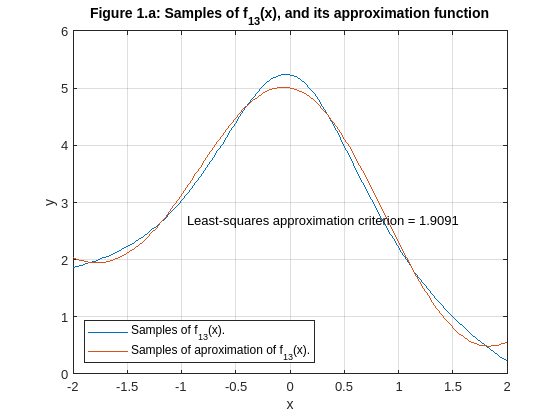


% Code for generation of figures 1.
txt = "Least-squares approximation criterion = " + j1;
figure(1)
plot(x,y);
hold on;grid on;
plot(x,y_approx1);
title("Figure 1.a: Samples of f_{13}(x), and its approximation function")
legend("Samples of f_{13}(x).","Samples of aproximation of f_{13}(x).",'Location','southwest')
xlabel("x")
ylabel("y")
text(-0.95,2.7,txt)
hold off;




% TASK 2 ******************************************************************************
disp("Beggining of task 2.")

Beggining of task 2.


N =100

N = 100

k = 4

k = 4

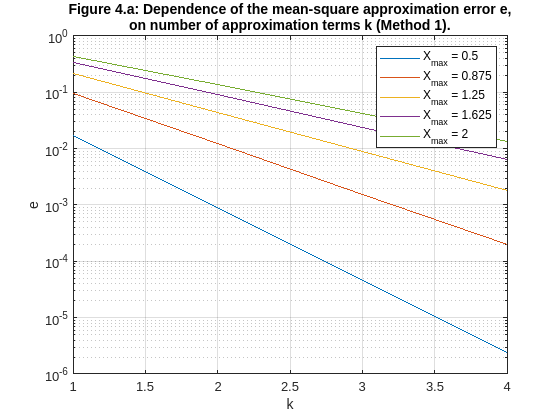


% Generation of vector of mean-square approximation errors. The function
% handle e(x,y,k,N) is defined for this purpose.
e1 = @(X,Y,L,N) sqrt( J(X,P1(Phi(X,L),Y))/N );
e2 = @(X,Y,L,N) sqrt( J(X,P2(Phi(X,L),Y))/N );
e3 = @(X,Y,L,N) sqrt( J(X,P3(Phi(X,L),Y))/N );
K = 1:k;
X_max = linspace(0.5,2,5);
E = zeros(5,size(K,2));

% Code for generation of figure 2.
figure(2)
for j = 1:5        
    x = linspace(-X_max(j), X_max(j), N);
    y = f13(x);
    for i = 1:size(K,2)
        E(j,i) = e1(x,y,K(i),N);
    end        
    plot(K,E(j,:));
    hold on;grid on;
end    
legend("X_{max} = " + X_max(1),"X_{max} = " + X_max(2),"X_{max} = " + X_max(3),"X_{max} = " + X_max(4),"X_{max} = " + X_max(5))
yscale("log")
title(["Figure 4.a: Dependence of the mean-square approximation error e,","on number of approximation terms k (Method 1)."])
xlabel("k")
ylabel("e")
hold off;

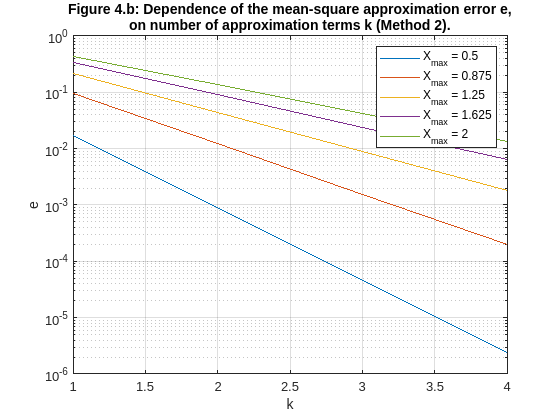


% Code for generation of figure 3.
figure(3)
for j = 1:5        
    x = linspace(-X_max(j), X_max(j), N);
    y = f13(x);
    for i = 1:size(K,2)
        E(j,i) = e2(x,y,K(i),N);
    end        
    plot(K,E(j,:));
    hold on;grid on;
end    
legend("X_{max} = " + X_max(1),"X_{max} = " + X_max(2),"X_{max} = " + X_max(3),"X_{max} = " + X_max(4),"X_{max} = " + X_max(5))
yscale("log")
title(["Figure 4.b: Dependence of the mean-square approximation error e,","on number of approximation terms k (Method 2)."])
xlabel("k")
ylabel("e")
hold off;

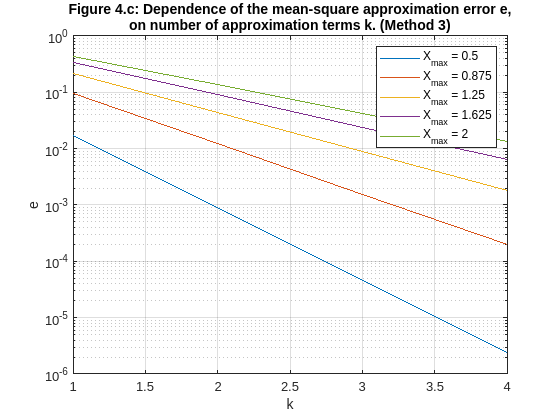


% Code for generation of figure 4.
figure(4)
for j = 1:5        
    x = linspace(-X_max(j), X_max(j), N);
    y = f13(x);
    for i = 1:size(K,2)
        E(j,i) = e3(x,y,K(i),N);
    end        
    plot(K,E(j,:));
    hold on;grid on;
end    
legend("X_{max} = " + X_max(1),"X_{max} = " + X_max(2),"X_{max} = " + X_max(3),"X_{max} = " + X_max(4),"X_{max} = " + X_max(5))
yscale("log")
title(["Figure 4.c: Dependence of the mean-square approximation error e,","on number of approximation terms k. (Method 3)"])
xlabel("k")
ylabel("e")
hold off;


% TASK 3 ******************************************************************************
disp("Beggining of task 3.")

Beggining of task 3.


% R is the number of trials of error generation used in finding the
% expected value of mean-square approximation errors.
N =10

N = 10

R = 10

R = 10

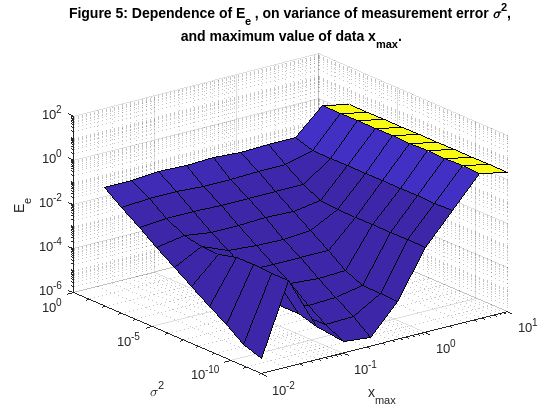


% Generation of vector of exemplary values of maximum values of the data
% vector x, X_max (X_max ranges from [10^-2,10], and x is in the range [-x_max,x_max]),
% and vector of exemplary values of the variance 
% of the normally distributed measurement error, sig2, from which the standard 
% deviation is calculated (The variances are taken from the interval [10^-12,10^-2]).
X_max = logspace(-2,1,N);
sig2 = logspace(-12,-2,N);

% Calculation of the expected values of mean-square approximation errors for 
% every combination of variance and maximum data value ([10^-12,10^-2]X[10^-2,10]).
% The results are stored in the NXN matrix T. Each expected value of mean-square 
% approximation errors is calculated as the expected value of R many
% individual mean-square approximation errors, each calculated for a newly generated vector
% of measurement errors. E is a vector which temporarily stores these intermediate 
% individual results.
T = zeros(N);
for s = 1:N
    for i = 1:N
        x = linspace(-X_max(i),X_max(i),N);
        y = f13(x);
        E = zeros(1,R);
        for r = 1:R
            y_err = y + sqrt(sig2(s))*randn(1,N);
            E(1,r) = e1(x,y_err,3,N);
        end
        exc = sqrt(sum(E.^2));
        T(s,i) = exc;
    end
end

% Code for generation of figure 5
figure(5)
surf(X_max,sig2,T)
hold on;grid on;
title(["Figure 5: Dependence of E_e , on variance of measurement error \sigma^2," ," and maximum value of data x_{max}."])
zscale("log");
yscale("log")
xscale("log")
xlabel("x_{max}")
ylabel("\sigma^2")
zlabel("E_e")
hold off;


% TASK 4 ******************************************************************************
disp("Beggining of task 4.")

Beggining of task 4.



% t is the number of trails when comparing the runtime difference between
% all methods for finding p.
N = 100

N = 100

x_max = 0.5

x_max = 0.5000

k = 4

k = 4

t = 100

t = 100

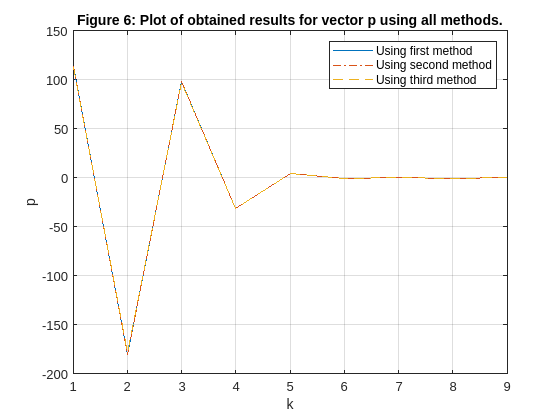


x = linspace(-x_max, x_max, N);
y = f13(x);

% Generating vectors of the results of the approximated function f13(x).

% Generating the matrix Phi as described in the document, which is used to
% find the vector of parameters p which minimizes the criterion of the least-squares 
% approximation of f13(x). The function used to generate these matrices,
% Phi(x,k), is defined in the file Phi.m .
M = Phi(x,k);

% Generation of vector of paramters p using methods described in the report. 
% The built-in functions tic,toc are used to measure the rutime of each method. 
% This measurement is repeated t many times.
m1 = zeros(1,t);
m2 = zeros(1,t);
m3 = zeros(1,t);
for i = 1:t
    t1 = tic;
    p1 = pinv(M)*y'; 
    m1(1,i) = toc(t1);
   
    t2 = tic;
    p2 = M\y';
    m2(1,i) = toc(t2);

    t3 = tic;
    p3 = (M'*M)\(M'*y');
    m3(1,i) = toc(t3);
end

% Code for generation of figure 6,7.
figure(6)
plot(1:2*k+1, p1)
hold on;grid on;
plot(1:2*k+1, p2,"-.")
plot(1:2*k+1, p3,"--")
title("Figure 6: Plot of obtained results for vector p using all methods.")
legend("Using first method","Using second method","Using third method")
ylabel("p")
xlabel("k")
hold off;

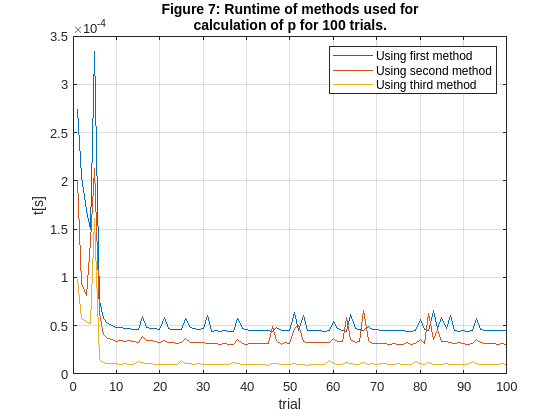


figure(7)
plot(1:t,m1)
hold on;grid on;
plot(1:t,m2)
plot(1:t,m3)
title(["Figure 7: Runtime of methods used for" ,"calculation of p for 100 trials."])
legend("Using first method","Using second method","Using third method")
xlabel("trial")
ylabel("t[s]")
hold off;